# Forward dynamics

Copyright (C) 1993-2018, by Peter I. Corke, http://www.petercorke.com

Forward dynamics is the computation of joint accelerations given position and velocity state, and actuator torques.  It is useful in simulation of a robo control system.

Consider a Puma 560 at rest in the zero angle pose, with zero applied joint  torques. The joint acceleration would be given by

mdl_puma560
p560.accel(qz, zeros(1,6), zeros(1,6))

ans =    -0.2462
   -8.6829
    3.1462
    0.0021
    0.0603
    0.0001


To be useful for simulation this function must be integrated.  fdyn() uses the MATLAB function ode45() to integrate the joint acceleration.  It also allows  for a user written function to compute the joint torque as a function of  manipulator state.

To simulate the motion of the Puma 560 from rest in the zero angle pose  with zero applied joint torques

tic
[t q qd] = p560.nofriction().fdyn(10, [], qz);
toc

Elapsed time is 1.726354 seconds.


and the resulting motion can be plotted versus time

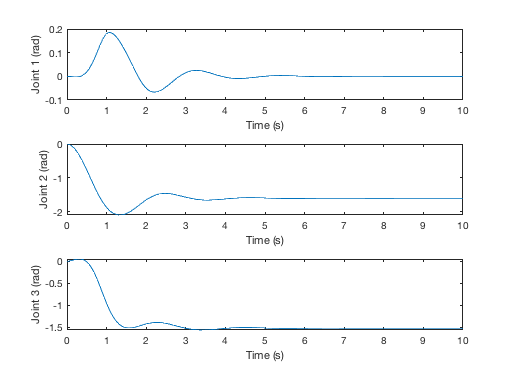

subplot(3,1,1); plot(t,q(:,1)); xlabel('Time (s)'); ylabel('Joint 1 (rad)')
subplot(3,1,2); plot(t,q(:,2)); xlabel('Time (s)'); ylabel('Joint 2 (rad)')
subplot(3,1,3); plot(t,q(:,3)); xlabel('Time (s)'); ylabel('Joint 3 (rad)')

Clearly the robot is collapsing under gravity, but it is interesting to  note that rotational velocity of the upper and lower arm are exerting  centripetal and Coriolis torques on the waist joint, causing it to rotate.

This can be shown in animation also

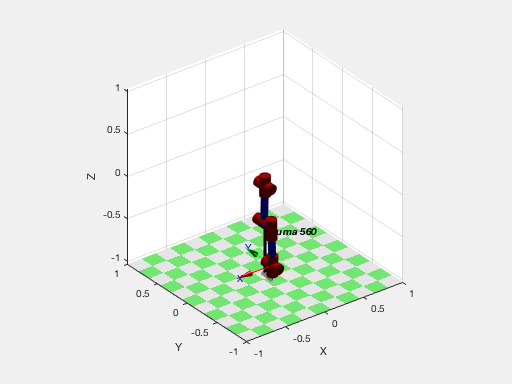

clf; p560.plot(q)